% F = [];
% for i = 0:255
%     F = [F, factor(i)];
% end
% 
% histogram(F, 256);
% xlabel('Prime');
% ylabel('Cumulative Frequency')

img = imread('barbara_bw.png');
F = [];
[h, w] = size(img);
L = [];
Primes = primes(225);
Powers = [];
for i = 1:h
    for j = 1:w
        fact = factor(img(i, j));
        F = [F, fact, 0];  
        % L = [L, length(fact)];
    end
end
% l = mean(L)
% m = mean(F)
% log2(l * m)
% hist = histogram(F, 256);
% xlabel('Prime');
% ylabel('Cumulative Frequency')
s = 1

s = 1

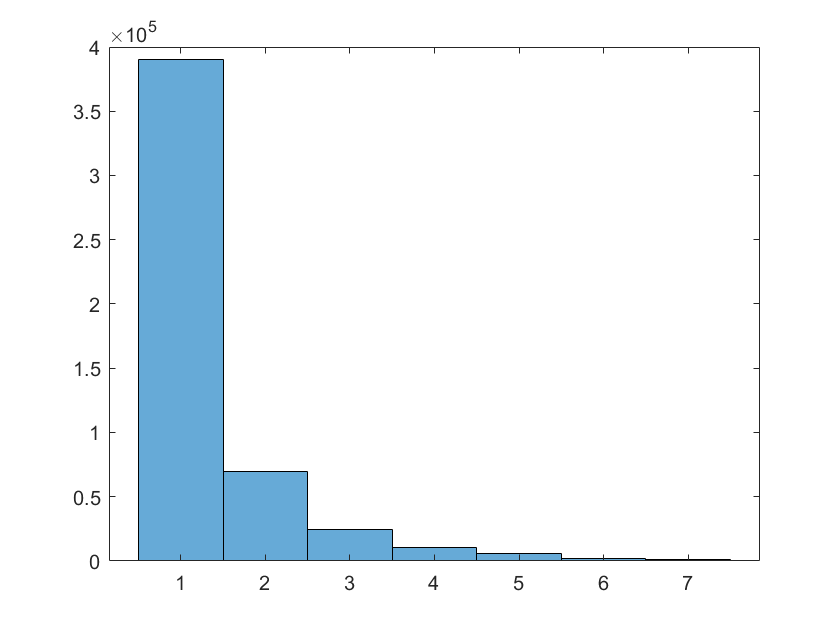

for t = 1:length(F)
    if F(t) == 0
        DF = F(s:t-1);
        UF = unique(DF);
        for i = 1:length(UF)
            Powers = [Powers, sum(DF == UF(i))];
        end
        s = t + 1;
    end
end
histogram(Powers);

mean(Powers)

ans = 1.3805